There are currently 3 defined kernel types:

EQ - exponential Quadratic (SE squared exponential)

RQ - Rational Quadratic (alpha=1)

Matern52

These kernels can be added subtracted multiplied and divided

The GP class takes a mean function and a kernel.

it then can be conditioned on data x and y and can then be trained using mean aposteriori HP selection.

clear all
%close all
clc

f1 = @(x) (6*x-2).^2.*sin(12*x-4);

xx = linspace(0,1,100)';
yy = f1(xx);

x1 = [0; 1*lhsdesign(6,1);1];
y1 = f1(x1);

%a = means.linear(4)*means.sine(1,3,0,1);
a = means.const(1);

%b = (kernels.Matern52(1,0.2) + kernels.EQ(0.2,0.4))*kernels.RQ(1,0.1);
b = kernels.Matern52(1,0.2);
b.signn = 0;

Z = GP(a,b);

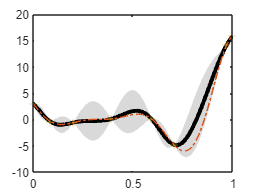

Z1 = Z.condition(x1,y1);

figure
utils.plotLineOut(Z1,1,1)
hold on
plot(xx,yy,'-.')
plot(x1,y1,'+')

% figure
% hold on
% 
% utils.plotLineOut(Z1,1,1)
% 
% for i = 1:30
%     ysamp = Z1.samplePosterior(xx);
%     plot(xx,ysamp,'LineWidth',0.05,'Color','k')
% end

tic
[Z2] = Z1.train();
toc

Elapsed time is 0.395250 seconds.


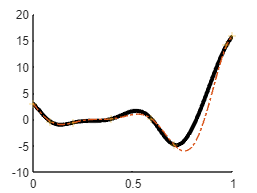

figure
hold on
utils.plotLineOut(Z2,1,1)
plot(xx,yy,'-.')
plot(x1,y1,'+')